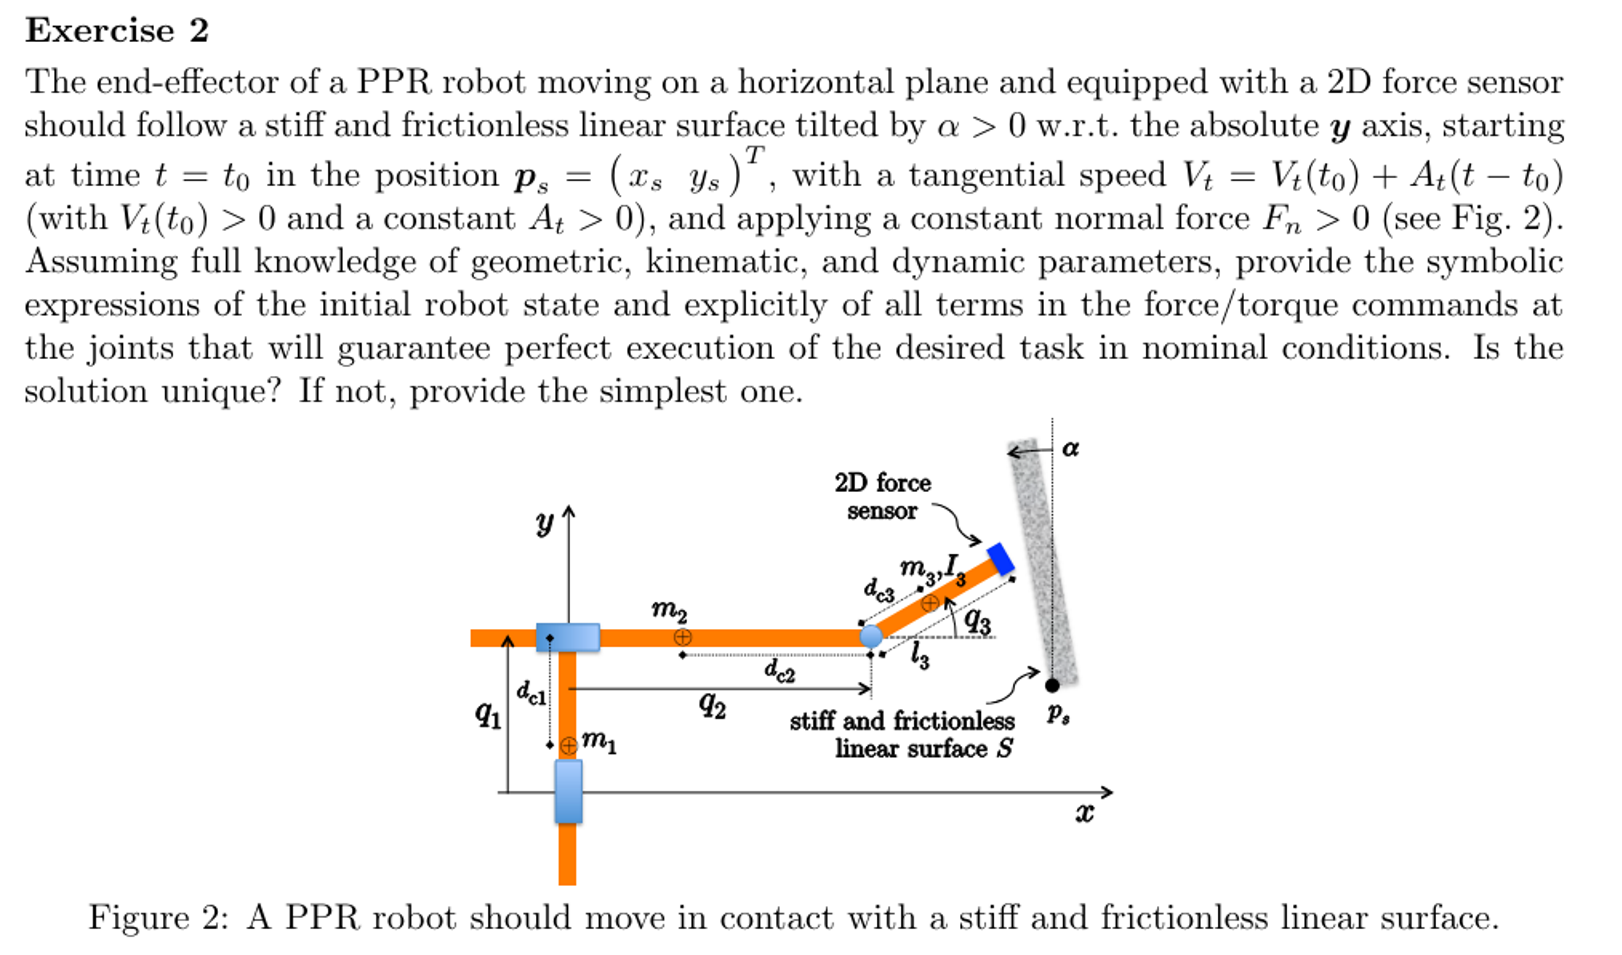

syms q1 q2 q3 q_dot_1 q_dot_2 q_dot_3 real
syms L m_1 m_2 m_3 I_1 I_2 I_3 l_1 l_2 l_3 g0 positive

% Dynamic model
% joint 1 
T1 = 0.5*m_1*(q_dot_1)^2

$$T1 = \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$


% joint 2 
x2 = q2-d_2;
y2 = q1;

vx2 = diff(x2,q1)*q_dot_1 + diff(x2,q2)*q_dot_2 + diff(x2,q3)*q_dot_3;
vy2 = diff(y2,q1)*q_dot_1 + diff(y2,q2)*q_dot_2 + diff(y2,q3)*q_dot_3;

T2_tr = 0.5*m_2*[vx2 vy2]*[vx2; vy2;];
T2_rot = 0;
T2 = T2_tr + T2_rot

$$T2 = \frac{m_{2}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{2}\,{{\dot{q}}_{2}}^{2}}{2}$$


% joint 3
x3 = q2+d_3*cos(q3);
y3 = q1+d_3*sin(q3);

vx3 = diff(x3,q1)*q_dot_1 + diff(x3,q2)*q_dot_2 + diff(x3,q3)*q_dot_3;
vy3 = diff(y3,q1)*q_dot_1 + diff(y3,q2)*q_dot_2 + diff(y3,q3)*q_dot_3;

T3_tr = 0.5*m_3*[vx3 vy3]*[vx3; vy3;];
T3_rot = 0.5*I_3*[0 0 q_dot_3]*[0; 0; q_dot_3;];
T3 = T3_tr + T3_rot

$$T3 = \frac{m_{3}\,{\left({\dot{q}}_{1}+d_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\right)}^{2}}{2}+\frac{m_{3}\,{\left({\dot{q}}_{2}-d_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\right)}^{2}}{2}+\frac{I_{3}\,{{\dot{q}}_{3}}^{2}}{2}$$


% Total Energy
T = T1+T2+T3

$$T = \frac{m_{3}\,{\left({\dot{q}}_{1}+d_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\right)}^{2}}{2}+\frac{m_{3}\,{\left({\dot{q}}_{2}-d_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\right)}^{2}}{2}+\frac{I_{3}\,{{\dot{q}}_{3}}^{2}}{2}+\frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{2}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{2}\,{{\dot{q}}_{2}}^{2}}{2}$$


% Inertia Matrix
M11 = diff(diff(T, q_dot_1), q_dot_1);
M12 = diff(diff(T, q_dot_1), q_dot_2);
M13 = diff(diff(T, q_dot_1), q_dot_3);

M21 = diff(diff(T, q_dot_2), q_dot_1);
M22 = diff(diff(T, q_dot_2), q_dot_2);
M23 = diff(diff(T, q_dot_2), q_dot_3);

M31 = diff(diff(T, q_dot_3), q_dot_1);
M32 = diff(diff(T, q_dot_3), q_dot_2);
M33 = diff(diff(T, q_dot_3), q_dot_3);

M = [M11, M12, M13;
     M21, M22, M23;
     M31, M32, M33];

M = simplify(M)

$$M = \left(\begin{array}{ccc} m_{1}+m_{2}+m_{3} & 0 & d_{3}\,m_{3}\,\cos\left(q_{3}\right)\\ 0 & m_{2}+m_{3} & -d_{3}\,m_{3}\,\sin\left(q_{3}\right)\\ d_{3}\,m_{3}\,\cos\left(q_{3}\right) & -d_{3}\,m_{3}\,\sin\left(q_{3}\right) & m_{3}\,{d_{3}}^{2}+I_{3} \end{array}\right)$$


% Coriolis and Centrifugal force
q  = [q1; q2; q3;];
dq = [q_dot_1; q_dot_2; q_dot_3;];
C = sym(zeros(3,3));

for i = 1:3
    for j = 1:3
        tmp = 0;
        for k = 1:3
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp);  % semplifico
    end
end

c_vec = simplify(C * dq);

disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\left(\begin{array}{ccc} 0 & 0 & -d_{3}\,m_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\\ 0 & 0 & -d_{3}\,m_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\\ 0 & 0 & 0 \end{array}\right)$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} -d_{3}\,m_{3}\,{{\dot{q}}_{3}}^{2}\,\sin\left(q_{3}\right)\\ -d_{3}\,m_{3}\,{{\dot{q}}_{3}}^{2}\,\cos\left(q_{3}\right)\\ 0 \end{array}\right)$$


% Direct Kinematics
p = [q2+l_3*cos(q3); q1+l_3*sin(q3);]

$$p = \left(\begin{array}{c} q_{2}+l_{3}\,\cos\left(q_{3}\right)\\ q_{1}+l_{3}\,\sin\left(q_{3}\right) \end{array}\right)$$

J = jacobian(p,[q1,q2,q3])

$$J = \left(\begin{array}{ccc} 0 & 1 & -l_{3}\,\sin\left(q_{3}\right)\\ 1 & 0 & l_{3}\,\cos\left(q_{3}\right) \end{array}\right)$$


px = q2+l_3*cos(q3)

$$px = q_{2}+l_{3}\,\cos\left(q_{3}\right)$$

py = q1+l_3*sin(q3)

$$py = q_{1}+l_{3}\,\sin\left(q_{3}\right)$$


vx = diff(px,q1)*q_dot_1+diff(px,q2)*q_dot_2+diff(px,q3)*q_dot_3

$$vx = {\dot{q}}_{2}-l_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)$$

vy = diff(py,q1)*q_dot_1+diff(py,q2)*q_dot_2+diff(py,q3)*q_dot_3

$$vy = {\dot{q}}_{1}+l_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)$$


ax = diff(vx,q1)*q_dot_1+diff(vx,q2)*q_dot_2+diff(vx,q3)*q_dot_3

$$ax = -l_{3}\,{{\dot{q}}_{3}}^{2}\,\cos\left(q_{3}\right)$$

ay = diff(vy,q1)*q_dot_1+diff(vy,q2)*q_dot_2+diff(vy,q3)*q_dot_3

$$ay = -l_{3}\,{{\dot{q}}_{3}}^{2}\,\sin\left(q_{3}\right)$$